clc
clear all

load("theta_coverage.mat")
load("gamma_coverage.mat")

theta_coverage = theta_coverage_for_n;
gamma_coverage = gamma_coverage_for_n;

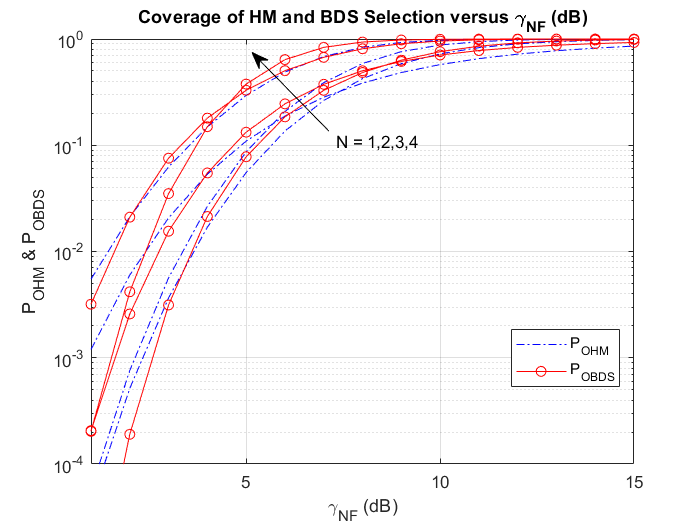

gamma_NF_db = [1:15];
gamma_NF = 10.^(gamma_NF_db/10);

figure
semilogy(gamma_NF_db, gamma_coverage, '-.b');
hold on
semilogy(gamma_NF_db, theta_coverage, '-or');

legend({'P_{OHM}', '', '', '', 'P_{OBDS}'}, 'Location', 'best')


xlabel('\gamma_{NF} (dB)'); ylabel('P_{OHM} & P_{OBDS}');
title('Coverage of HM and BDS Selection versus \gamma_{NF} (dB)')
grid on, hold on
ylim([1e-4 1])
xlim([1 15])
xticks(0:5:15)

annotation('textarrow', [0.47,0.36], [0.75,0.9], 'String', 'N = 1,2,3,4', 'LineWidth', 0.1);